# A

clear all
U1=220

U1 = 220

U2=12

U2 = 12

I2=5

I2 = 5

% A.1.2.1
P2=U2*I2

P2 = 60

% A.1.2.2
niutr=0.86

niutr = 0.8600

Pg=P2/2*((niutr+1)/niutr)

Pg = 64.8837

% A.1.2.3
J=3

J = 3

Sfe=1.2*sqrt(Pg*(1+niutr)/(J*niutr))

Sfe = 8.2072

% A.1.2.5
I1=Pg/U1

I1 = 0.2949

% A.1.2.6
R2N=U2/I2

R2N = 2.4000

% A.1.2.7
R2=1/100*R2N

R2 = 0.0240

% A.1.2.8
R1=0.5/100*(U1/I1)

R1 = 3.7297

% A.1.2.9
R2star=R2+R1*(U2/U1)^2

R2star = 0.0351

% A.2
% A.2.2.2
Umax21=sqrt(2)*U2

Umax21 = 16.9706

Ustarmax21=2.12*U2

Ustarmax21 = 25.4400


I2dc=1.5*0.7*I2

I2dc = 5.2500

rd=0.12

rd = 0.1200

k=2

k = 2

Ip=(sqrt(2)*U2)/(R2star+k*rd)

Ip = 61.6894

Cf=18.75*1e-3

Cf = 0.0187

deltat=(R2star+k*rd)*Cf

deltat = 0.0052

% A.3
pi=67/100;
po=10/100;
RSN=U2/I2

RSN = 2.4000

% A.3.2
q=pi/po

q = 6.7000

% A.3.2.2
Rrt=R2star+k*rd

Rrt = 0.2751

% A.3.2.3
Cfstar=1600*q*(Rrt+RSN)/Rrt/RSN;
Cfstar=Cfstar*1e-6

Cfstar = 0.0434

Rr=Rrt

Rr = 0.2751

% A.3.2.4
deltaUd=0.75;
Eo=1.41*U2-k*deltaUd

Eo = 15.4200

% A.3.2.5
R0=RSN;
kr=Rr/R0

kr = 0.1146

C0=Cfstar;
wCR=314*C0*R0

wCR = 32.7324

% from table 7 
ku=0.7

ku = 0.7000

% A.3.2.5
CfstarStar=wCR/314/R0

CfstarStar = 0.0434


%
C=(Cfstar+CfstarStar)/2

C = 0.0434

## B


% B1a
% 1)
miu=0.5

miu = 0.5000

% 2)
RSN

RSN = 2.4000

% 3)
Udc=ku*sqrt(2)*U2

Udc = 11.8794

% 4)
Udcmax=sqrt(2)*U2

Udcmax = 16.9706

% 5)
Vo=miu*Udc

Vo = 5.9397

% 6)
Io=Vo/RSN

Io = 2.4749

% 7)
deltaIL=0.2*Io

deltaIL = 0.4950

% 8)
deltaVo=2/100*Vo

deltaVo = 0.1188

% 9)
fc=20*1e3

fc = 20000


% 1.
L=(Udcmax-Vo)*miu/fc/deltaIL

L = 5.5714e-04

L=L*1e3

L = 0.5571

% 2.
C_2=(deltaIL*miu)/fc/deltaVo*1e3

C_2 = 0.1042

C

C = 0.0434

% alegem tranzistorul


Utranzistor=2*sqrt(2)*U2

Utranzistor = 33.9411

Itranzistor=1.5*Io

Itranzistor = 3.7123

Rs=RSN;
% the reference voltacge

## C

A=8;
L=L*10;
C=C_2

C = 0.1042

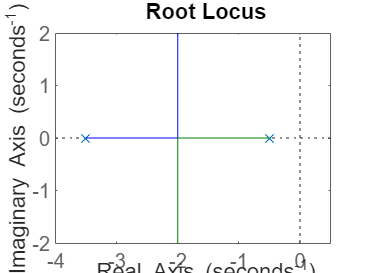

H=tf(1,[L*C L/Rs 1]);
Hol=1/2/A*sqrt(2)*ku*U2*H;
rlocus(Hol)

kp=12

kp = 12

kr=0.5;
    
